Let's start by fixing the path

clear
clc

full_path='D:\MATLAB AP Package Beta\';
project_path='D:\MATLAB AP Package Beta\Scratch\Week 7\';

restoredefaultpath;
addpath(genpath([full_path,'Data\']));
addpath(genpath([full_path,'Functions\']));
addpath(genpath(project_path));
cd(project_path);

clear full_path project_path  


## Combining anomalies:

Let's read in and fill in the 23 anomalies from Novy-Marx and Velikov (2016):

clear
clc

load dates
load me
load ret
load NYSE
load tcosts
load ff

% Read the signals data
[anoms23, labels23] = getAnomalySignals('novyMarxVelikovAnomalies.csv', 1, 2);
nAnoms = size(anoms23, 3);
nStocks = size(ret, 2);

filledAnoms = nan(size(anoms23));
for i = 1:nAnoms
    % Fill the months for the annual ones
    var = FillMonths(anoms23(:, :, i));
    
    % Create a monthly rank and standardize to be between -0.5 and 0.5
    var = tiedrank(var')';
    var = (var - 1) ./ (max(var, [], 2)-1);
    var = var - 0.5;        
    
    % Fill the observations with market with the median for this
    % characteristic (i.e., 0)
    indToZero = isnan(var) & isfinite(me);    
    var(indToZero) = 0;
    
    % Set to NaN all observations where we don't have a market cap
    var(isnan(me)) = nan;
    
    % Assign to the new 3-d array
    filledAnoms(:, :, i) = var;      
end

Let's start with just combining the ranks:

%%

eret = sum(filledAnoms,3);
eret(isnan(me)) = nan;


ind = makeUnivSortInd(eret, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'factorModel', 6);

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 6-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      rmw      cma      umd
                                                                                          
               1   -0.214   -0.559    1.058    0.247   -0.248    -0.331   -0.184    -0.424
                  [-1.05]  [-8.59]  [66.97]  [11.09]  [-8.27]  [-10.85]  [-4.08]  [-27.56]
                                                                                          
               2    0.198   -0.405    1.031    0.060   -0.030   -0.073   -0.119    -0.218 
                  [ 1.10]  [-6.86]  [71.87]  [ 2.95]  [-1.08]  [-2.62]  [-2.89]  [-15.60] 
                                

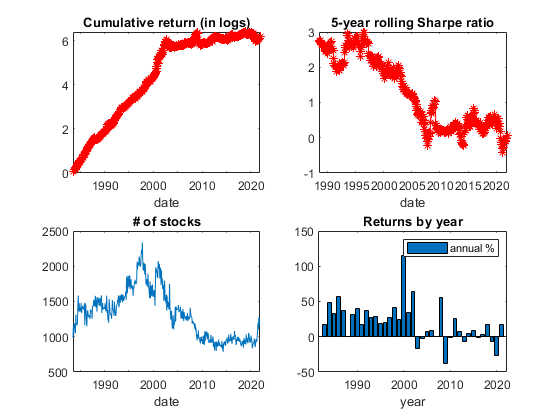

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 6-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      rmw      cma      umd
                                                                                         
               1   -0.105   -0.471    1.063    0.307   -0.209   -0.357   -0.171    -0.426
                  [-0.35]  [-5.50]  [50.89]  [ 9.97]  [-5.54]  [-9.08]  [-3.00]  [-22.02]
                                                                                         
               2    0.169   -0.438    1.037    0.091    0.006   -0.094   -0.096    -0.207
                  [ 0.68]  [-5.64]  [54.79]  [ 3.28]  [ 0.18]  [-2.63]  [-1.85]  [-11.82]
                                      


ind = makeUnivSortInd(eret, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'factorModel', 6, ...
                                       'timePeriod', 198306);

save eret_rank eret

Let's look at a combined rank based on Fama-MacBeths:

%%

s = find(dates==197306);
nMonths = length(dates);

% Determine the rolling period
T = 120;


eret = nan(size(me));
tic;
parfor i=(s+T+1):nMonths
    if mod(i,120)==0
        fprintf('Done until %d @ %s.\n',dates(i),char(datetime('now')));
    end
    
    rollPeriodChars = filledAnoms(i-T+1:i, :, :);
    
    fmbX = reshape(rollPeriodChars, T, nStocks * nAnoms);
    fmbY = 100*ret(i-T+1:i, :);
    
    res = runFamaMacBeth(fmbY, fmbX, dates(i-T+1:i), 'printResults', 0);
    eret(i,:) = [permute(filledAnoms(i,:,:),[2 3 1])*res.bhat(2:end)']';
end

Done until 199511 @ 26-Apr-2022 22:44:29.
Done until 198511 @ 26-Apr-2022 22:46:42.
Done until 200511 @ 26-Apr-2022 22:51:16.
Done until 201511 @ 26-Apr-2022 22:53:22.


toc;

Elapsed time is 948.654912 seconds.


     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 6-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      rmw      cma      umd
                                                                                         
               1   -0.019   -0.535    1.095    0.266   -0.122   -0.286   -0.152    -0.282
                  [-0.06]  [-4.71]  [39.60]  [ 6.55]  [-2.44]  [-5.49]  [-2.01]  [-11.01]
                                                                                         
               2    0.493   -0.131    0.987    0.139   -0.016   -0.095   -0.079   -0.115 
                  [ 2.11]  [-1.66]  [51.38]  [ 4.92]  [-0.47]  [-2.63]  [-1.50]  [-6.45] 
                                      

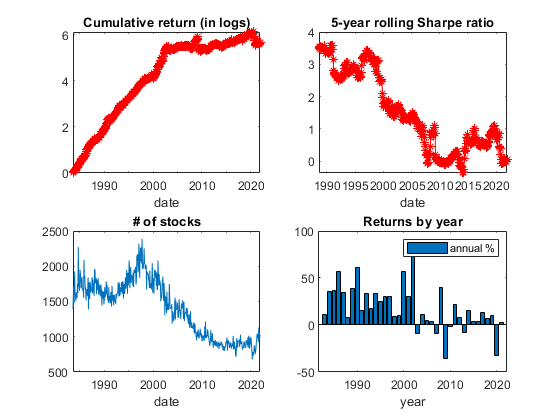

ind = makeUnivSortInd(eret, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'factorModel', 6);

save eret_fmb eret


Let's do Partial Least Squares from Light, Maslov, and Rytchkov (2017)

     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 6-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      rmw      cma      umd
                                                                                        
               1    0.058   -0.497    1.185    0.378    0.007   -0.245   -0.256   -0.293
                  [ 0.19]  [-2.96]  [30.14]  [ 6.52]  [ 0.10]  [-3.23]  [-2.20]  [-7.65]
                                                                                        
               2    0.402   -0.167    1.071    0.187    0.026   -0.049   -0.221   -0.189
                  [ 1.61]  [-1.46]  [39.95]  [ 4.73]  [ 0.52]  [-0.96]  [-2.79]  [-7.25]
                                            

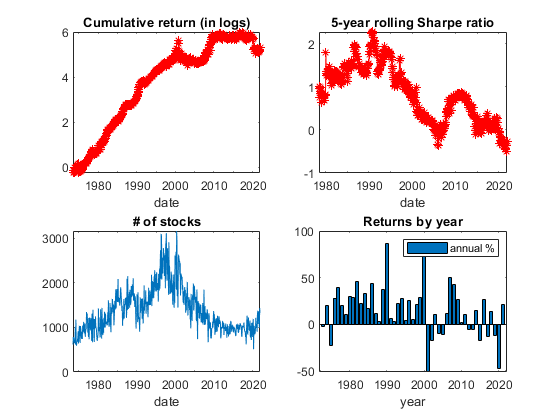

eret = nan(size(ret));
lambda = nan(nMonths, nAnoms);
for i = find(dates==197306):nMonths
    y = ret(i,:)';
    x = permute(filledAnoms(i-1, :, :), [2 3 1]);
    xt = permute(filledAnoms(i, :, :), [2 3 1]);
    
    % Step 1
    const = ones(nStocks, 1);
    for j = 1:nAnoms
        res = nanols(y, x(:, j));
        lambda(i,j) = res.beta;
    end
    
    % Step 2
    const = ones(nAnoms, 1);
    for j = 1:nStocks
        res = nanols(xt(j,:)', lambda(i, :)');
        eret(i, j) = res.beta;
    end
end
    
ind = makeUnivSortInd(eret, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'factorModel', 6);


save eret_pls eret


Next, let's use Kelly, Priutt, and Su's (2019) IPCA. The code here is a version of their posted code for the paper. It uses their num_IPCA_estimate_ALS().m function, which is stored in the /Function/Cookbook functions/ directory of the package.

clear chars

xret = (ret - repmat(rf, 1, nStocks))';

for i = 1:nAnoms
    chars(:, :, i) = lag(filledAnoms(:, :, i), 1, nan);
end

chars = permute(chars,[2 1 3]);
LOC = ~isnan(chars);
LOC = all(LOC, 3) & ~isnan(xret);

s = find(dates == 197306);

% keepthese = sum(LOC)>=max(100, 23+2);
LOC   = LOC(:, s:end);
chars = chars(:, s:end,:);
xret  = xret(:, s:end);
tdates = dates(s:end);


% Add a constant
chars(:, :, nAnoms+1)  = 1;
[~, T, L]         = size(chars);
Nts = sum(LOC);

% Construct X, W, X
chars = permute(chars, [1 3 2]); % chars is now NxLxT
Z     = chars;
bigW  = nan(L, L, T);
bigX  = nan(L, T);
for t = 1:T % parfor makes it too big
    
    % W = Z'Z
    bigW(:,:,t) = (1/Nts(t)) * Z(LOC(:,t),:,t)' * Z(LOC(:,t),:,t); 
    
    % X = Z'r
    bigX(:,t)   = (1/Nts(t)) * Z(LOC(:,t),:,t)' * xret(LOC(:,t),t); 
end

K = 5;
als_opt.MaxIterations = 10000;
als_opt.Tolerance     = 1e-6;
bigNts = sum(LOC);

[N, ~, T] = size(Z);

% eret = nan(size(ret));
temp_eret = nan(T, nStocks);

% Calculate restricted model first
% Initial guess for GammaBeta & the factor(s)    
for t=120:T-1
    if mod(t,120)==0
        fprintf('Done with first until %d @ %s.\n',tdates(t),char(datetime('now')));
    end
    X   = bigX(:, t-119:t);    % this is X known through t
    W   = bigW(:, :, t-119:t); % this is W known through t
    Nts = bigNts(t-119:t);     % this is Nts known through t
    
    [GammaBeta_initial, s, v] = svds(X, K);
    if t==120
        GB_Old      = GammaBeta_initial;
        F_Old       = s*v'; %ones(K,T);%
    else
        GB_Old      = GB_New;
        F_Old       = [F_New(:,2:end) s*v(end,:)'];
    end
    
    % Iterate until you reach tolerance or max iterations
    tol         = 1;
    iter        = 0;
    while iter <= als_opt.MaxIterations && tol > als_opt.Tolerance
        [GB_New, F_New] = num_IPCA_estimate_ALS(GB_Old, W, X, Nts);
        tol     = max([ abs(GB_New(:) - GB_Old(:)); abs(F_New(:)-F_Old(:)) ]);
        F_Old   = F_New;
        GB_Old  = GB_New;
        iter    = iter+1;
    end

    GammaBeta = GB_New;
    Lambda = mean(F_New,2);        
    
    temp_eret(t, :) = (Z(:,:,t+1) * GammaBeta * Lambda)';    
end

Done with first until 198305 @ 26-Apr-2022 23:05:06.
Done with first until 199305 @ 26-Apr-2022 23:06:13.
Done with first until 200305 @ 26-Apr-2022 23:06:51.
Done with first until 201305 @ 26-Apr-2022 23:07:32.


     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 6-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      rmw      cma      umd
                                                                                         
               1    0.094   -0.406    1.078    0.299   -0.189   -0.223   -0.134    -0.319
                  [ 0.32]  [-3.44]  [37.53]  [ 7.07]  [-3.65]  [-4.14]  [-1.71]  [-11.98]
                                                                                         
               2    0.512   -0.152    1.018    0.147    0.003   -0.045   -0.041   -0.137 
                  [ 2.16]  [-2.00]  [54.79]  [ 5.37]  [ 0.09]  [-1.28]  [-0.80]  [-7.98] 
                                      

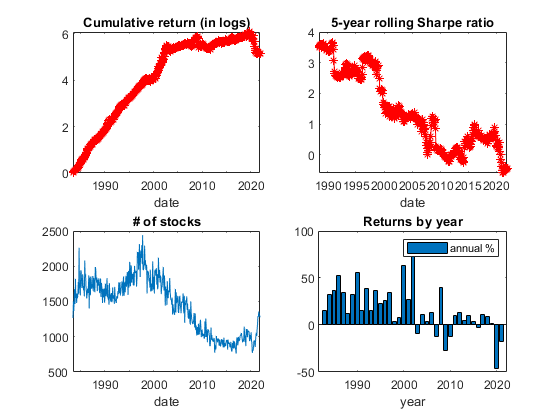


s = find(dates == 197306);
eret(s:end, :) = temp_eret;

ind = makeUnivSortInd(eret, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'factorModel', 6);


save eret_ipca eret



Let's do LASSO next:

% Store a few constants
T = 120;
s = find(dates==197306);
nAnoms = size(filledAnoms, 3);
nMonths = length(dates);
nStocks = size(ret, 2);
nObs = nMonths * nStocks;

chars = permute(filledAnoms, [2 1 3]);

% Prepare the matrices for the LASSO estimation
lassoY = reshape(ret, nObs, 1);
lassoX = [];

for i = 1:nAnoms
    temp = lag(chars(:, :, i)', 1, nan);
    lassoX = [lassoX reshape(temp, nObs, 1)];
end

lassoDates = reshape(repmat(dates, 1, nStocks), nObs, 1);

% ind=[isfinite(lassoY) & sum(isfinite(lassoX),2)>0];
ind = isfinite(sum([lassoY lassoX], 2));

lassoY = lassoY(ind, :);
lassoX = lassoX(ind, :);
lassoDates = lassoDates(ind, :);

% Initialize an estimate the betas and expected returns
bhat = nan(nMonths, nAnoms);
eret = nan(size(me));

tic;
parfor i = (s+T):nMonths
    if mod(i,120) == 0
        fprintf('Done until %d @ %s.\n', dates(i), char(datetime('now')));
    end
    
    ind = lassoDates <= dates(i) & ...
          lassoDates >= dates(i-T+1);
    y = lassoY(ind);
    x = lassoX(ind,:);

        
    [B, fitInfo] = lasso(x, y, 'CV', 5);
    
    minMSE = find(fitInfo.MSE == min(fitInfo.MSE));
    
    eret(i, :) = [permute(chars(:, i, :), [1 3 2]) * B(:, minMSE)]';
    bhat(i, :) = B(:,minMSE)';        
end

Done until 199511 @ 26-Apr-2022 23:39:40.
Done until 198511 @ 26-Apr-2022 23:56:42.
Done until 200511 @ 27-Apr-2022 00:53:13.
Done until 201511 @ 27-Apr-2022 01:09:36.


toc;

Elapsed time is 7701.956266 seconds.


     ---------------------------------------------------------------------------- 
              Value-weighted portfolio sort, 1-month holding period
              Excess returns, alphas, and loadings on:
              Fama and French 6-factor model
     ---------------------------------------------------------------------------- 
                    xret    alpha      mkt      smb      hml      rmw      cma      umd
                                                                                         
               1   -0.021   -0.505    1.054    0.216   -0.058   -0.244   -0.222    -0.283
                  [-0.07]  [-5.55]  [47.50]  [ 6.62]  [-1.45]  [-5.85]  [-3.67]  [-13.75]
                                                                                         
               2    0.404   -0.281    1.054    0.160    0.031   -0.121   -0.085   -0.063 
                  [ 1.65]  [-3.48]  [53.59]  [ 5.52]  [ 0.88]  [-3.26]  [-1.59]  [-3.49] 
                                      

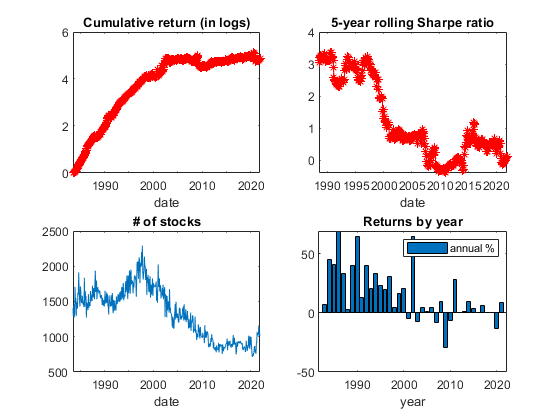


ind = makeUnivSortInd(eret, 10, NYSE);
res = runUnivSort(ret, ind, dates, me, 'factorModel', 6);


save eret_lasso eret


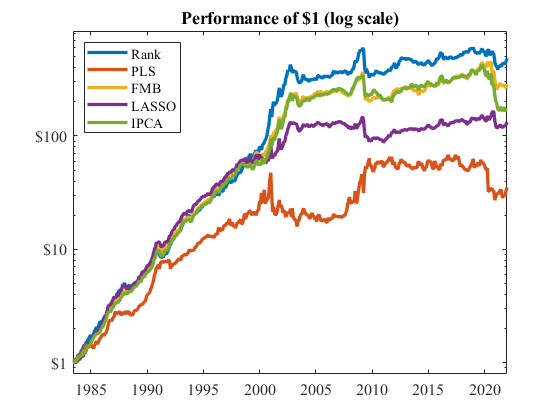

clear
clc

load ret
load dates
load me
load NYSE
load tcosts

eret_rank  = load('eret_rank.mat');
eret_fmb   = load('eret_fmb.mat');
eret_pls   = load('eret_pls.mat');
eret_lasso = load('eret_lasso.mat');
eret_ipca  = load('eret_ipca.mat');

ind = makeUnivSortInd(eret_rank.eret, 10, NYSE);
res_rank = runUnivSort(ret, ind, dates, me, 'timePeriod', 198306, ...
                                            'printResults', 0, ...
                                            'plotFigure', 0, ...
                                            'tcosts', tcosts);

ind = makeUnivSortInd(eret_fmb.eret, 10, NYSE);
res_fmb = runUnivSort(ret, ind, dates, me, 'timePeriod', 198306, ...
                                            'printResults', 0, ...
                                            'plotFigure', 0, ...
                                            'tcosts', tcosts);

ind = makeUnivSortInd(eret_pls.eret, 10, NYSE);
res_pls = runUnivSort(ret, ind, dates, me, 'timePeriod', 198306, ...
                                            'printResults', 0, ...
                                            'plotFigure', 0, ...
                                            'tcosts', tcosts);


ind = makeUnivSortInd(eret_lasso.eret, 10, NYSE);
res_lasso = runUnivSort(ret, ind, dates, me, 'timePeriod', 198306, ...
                                            'printResults', 0, ...
                                            'plotFigure', 0, ...
                                            'tcosts', tcosts);

ind = makeUnivSortInd(eret_ipca.eret, 10, NYSE);
res_ipca = runUnivSort(ret, ind, dates, me, 'timePeriod', 198306, ...
                                            'printResults', 0, ...
                                            'plotFigure', 0, ...
                                            'tcosts', tcosts);


% Plot the gross returns
grossret = [res_rank.pret(:, end) res_pls.pret(:, end) res_fmb.pret(:, end) res_lasso.pret(:, end) res_ipca.pret(:, end)];
figure;
ibbots(grossret, res_rank.dates, 'legendLabels', {'Rank','PLS','FMB','LASSO','IPCA'});

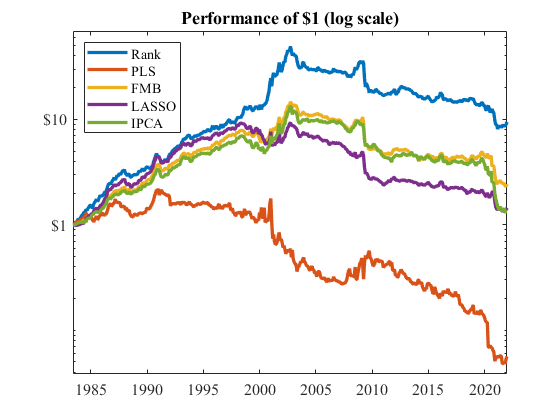


% Net returns
netret = [res_rank.netpret(:, end) res_pls.netpret(:, end) res_fmb.netpret(:, end) res_lasso.netpret(:, end) res_ipca.netpret(:, end)];
figure;
ibbots(netret, res_rank.dates, 'legendLabels', {'Rank','PLS','FMB','LASSO','IPCA'});

What happens to profits post 2000? Decimalization? Access to internet? High-frequency trading? Chordia, Subrahmanyam, and Tong (JAE, 2014) find similar results for individual anomalies.

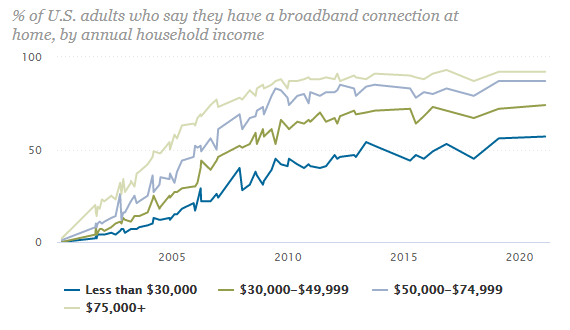

One of our results in Chen and Velikov (JFQA, Forthcoming):